Itable = readtable("Firm.xlsx",ReadRowNames=true)

Itable = 107×9 table
                Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0212    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    P0213    {'GRI'      }    {'ALBERTO'      }    {'

selectedcolumns =["Wage","CommutingTime","SmartWorkHours" "Seniority"];

X = Itable(:,selectedcolumns);

X=Itable{:,selectedcolumns};

% compute the devaition matix and standardized devaition matrix Z
deviationMatrix = X-mean(X);
standardizedMatrix = deviationMatrix ./std(X);

% calculate he covariance matrix  via cov, and also by matrix
% multiplication of of devaition matrix
covarianceMatrix = cov(X);
covarianceMatrixManual = (deviationMatrix' * deviationMatrix) / (size(X, 1) - 1);
% calculate the coorelation matrix via corr
correlationMatrix = corr(X);

% in random ariable n=12 perfume bottle weight and internal volume , the
% sample correlation between weight and volume is r =0.54 at significan
% level alpha =0.01, state your conclusion. compute the p-value of the
% test. write your code generally so it works for arbitrary inputs n, aplha
% and r. also display a reminder of the assumption required (i.e a random
% sample from a bivariate normal population).
n = 12; % sample size
alpha = 0.01; % significance level
r = 0.54; % sample correlation coefficient
% compute the test significant t_r
t_r = r * sqrt((n - 2) / (1 - r^2)); % compute the t statistic
p_value = 2 * (1 - tcdf(abs(t_r), n - 2)); % compute the two-tailed p-value
fprintf('Assumptions: Random sample from a bivariate normal population.\n');

Assumptions: Random sample from a bivariate normal population.


fprintf('Computed p-value: %.4f\n', p_value);

Computed p-value: 0.0699


% from the four quantitatives in X , compute manually the p-values of zero-
% correlation test for every pair and compare with those returned by corr.
p_valuesManual = zeros(size(X, 2)); % Initialize p-values array
for i = 1:size(X, 2)
    for j = i+1:size(X, 2)
        r_ij = corr(X(:, i), X(:, j)); % Compute sample correlation
        t_ij = r_ij * sqrt((n - 2) / (1 - r_ij^2)); % Compute t statistic
        p_valuesManual(i, j) = 2 * (1 - tcdf(abs(t_ij), n - 2)); % Compute p-value
    end
end

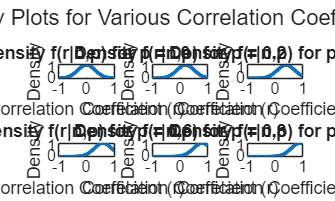

% Plot the density f(r|n,p) for  a sample of n=12 observations at
% p=0,0.2,0.4,0.6,0.8,0.9,in 2*3 grid of subplot. add dimamic title to each
% panel and global plot title
x =-1:0.01:1;
rho =[0,0.2,0.4,0.6,0.8,0.9]';
n=12;
rhos=num2str(rho);
ns=num2str(n);
close all
for i=1:length(rhos)
    subplot(2, 3, i);
    plot(x, normpdf(x, rho(i), 1/sqrt(n-2)), 'LineWidth', 2);
    title(['Density f(r|n,p) for p = ', rhos(i, :)]);
    xlabel('Correlation Coefficient (r)');
    ylabel('Density');
end
sgtitle('Density Plots for Various Correlation Coefficients');

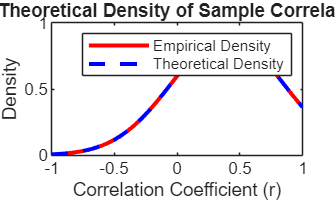

% emperical and theoretical densities of the sample correlation coefficent
% for n=7 and p=0.4
% Compute empirical and theoretical densities for n=7 and p=0.4
n_empirical = 7;
p_empirical = 0.4;
rho_empirical = linspace(-1, 1, 100);
empirical_density = normpdf(rho_empirical, p_empirical, 1/sqrt(n_empirical-2));
% using corrcdf
theoretical_density = normpdf(rho_empirical, p_empirical, 1/sqrt(n_empirical-2));
figure;
plot(rho_empirical, empirical_density, 'r-', 'LineWidth', 2); hold on;
plot(rho_empirical, theoretical_density, 'b--', 'LineWidth', 2);
legend('Empirical Density', 'Theoretical Density');
title('Empirical vs Theoretical Density of Sample Correlation Coefficient');
xlabel('Correlation Coefficient (r)');
ylabel('Density');
hold off;

% from X COMPUTE the spearman rank coorelation matrix and also the p-values
% for testing zero rank correlation for each pair. Display both matrics
% using table and commment
% Compute Spearman rank correlation matrix and p-values
spearmanCorrMatrix = corr(X, 'Type', 'Spearman');
% Compute p-values for Spearman rank correlation matrix
spearmanPValues = zeros(size(spearmanCorrMatrix)); % Initialize p-values array
for i = 1:size(X, 2)
    for j = i+1:size(X, 2)
        [~, spearmanPValues(i, j)] = corr(X(:, i), X(:, j), 'Type', 'Spearman'); % Compute p-value
    end
end
% Display the Spearman correlation matrix and p-values as tables
spearmanCorrTable = array2table(spearmanCorrMatrix, 'VariableNames', selectedcolumns, 'RowNames', selectedcolumns);
spearmanPValuesTable = array2table(spearmanPValues, 'VariableNames', selectedcolumns, 'RowNames', selectedcolumns);
disp('Spearman Correlation Matrix:');

Spearman Correlation Matrix:


disp(spearmanCorrTable);

                        Wage      CommutingTime    SmartWorkHours    Seniority
                      ________    _____________    ______________    _________

    Wage                     1      0.064691          0.080903        0.78545 
    CommutingTime     0.064691             1           0.70092        0.10715 
    SmartWorkHours    0.080903       0.70092                 1        0.07042 
    Seniority          0.78545       0.10715           0.07042              1 



disp('Spearman P-Values Matrix:');

Spearman P-Values Matrix:


disp(spearmanPValuesTable);

                      Wage    CommutingTime    SmartWorkHours    Seniority 
                      ____    _____________    ______________    __________

    Wage               0         0.50797           0.40745       1.3023e-23
    CommutingTime      0               0         4.268e-17            0.272
    SmartWorkHours     0               0                 0          0.47105
    Seniority          0               0                 0                0



test = readtable("tagliatelle.xlsx",Sheet="Data");

test = 40×3 table
    moisture    ash     broken
    ________    ____    ______

      9.15      0.99      12  
       8.5      1.01     NaN  
       8.5         1      10  
      8.86      1.04     NaN  
      9.25      1.02      12  
      8.35      1.01      10  
         8         1       8  
      8.65       NaN       8  
      7.95      1.03       8  
       8.7      1.04      11  
       7.6      1.01     NaN  
       8.3      1.04      12  
      8.65      1.04       9  
       8.1      1.04       9  
      10.8      1.06     NaN  
      8.25       NaN      13  


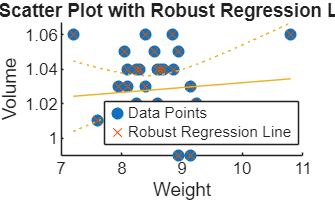

% scatter plot with outlier flagged by robust regression from table X
% Scatter plot with outlier flagged by robust regression from table X
figure;
scatter(test.moisture, test.ash, 'filled');
hold on;
mdl = fitlm(test.moisture, test.ash, 'RobustOpts', 'on');
plot(mdl);
xlabel('Weight');
ylabel('Volume');
title('Scatter Plot with Robust Regression Line');
legend('Data Points', 'Robust Regression Line');
hold off;

Itable = readtable("Firm.xlsx",ReadRowNames=true)

selectedcolumns =["Wage","CommutingTime","SmartWorkHours" "Seniority"];

X = Itable(:,selectedcolumns);

X=Itable{:,selectedcolumns};

% compute the devaition matix and standardized devaition matrix Z
deviationMatrix = X-mean(X);
standardizedMatrix = deviationMatrix ./std(X);

% calculate he covariance matrix  via cov, and also by matrix
% multiplication of of devaition matrix
covarianceMatrix = cov(X);
covarianceMatrixManual = (deviationMatrix' * deviationMatrix) / (size(X, 1) - 1);
% calculate the coorelation matrix via corr
correlationMatrix = corr(X);

% in random ariable n=12 perfume bottle weight and internal volume , the
% sample correlation between weight and volume is r =0.54 at significan
% level alpha =0.01, state your conclusion. compute the p-value of the
% test. write your code generally so it works for arbitrary inputs n, aplha
% and r. also display a reminder of the assumption required (i.e a random
% sample from a bivariate normal population).
n = 12; % sample size
alpha = 0.01; % significance level
r = 0.54; % sample correlation coefficient
% compute the test significant t_r
t_r = r * sqrt((n - 2) / (1 - r^2)); % compute the t statistic
p_value = 2 * (1 - tcdf(abs(t_r), n - 2)); % compute the two-tailed p-value
fprintf('Assumptions: Random sample from a bivariate normal population.\n');
fprintf('Computed p-value: %.4f\n', p_value);

% from the four quantitatives in X , compute manually the p-values of zero-
% correlation test for every pair and compare with those returned by corr.
p_valuesManual = zeros(size(X, 2)); % Initialize p-values array
for i = 1:size(X, 2)
    for j = i+1:size(X, 2)
        r_ij = corr(X(:, i), X(:, j)); % Compute sample correlation
        t_ij = r_ij * sqrt((n - 2) / (1 - r_ij^2)); % Compute t statistic
        p_valuesManual(i, j) = 2 * (1 - tcdf(abs(t_ij), n - 2)); % Compute p-value
    end
end

% Plot the density f(r|n,p) for  a sample of n=12 observations at
% p=0,0.2,0.4,0.6,0.8,0.9,in 2*3 grid of subplot. add dimamic title to each
% panel and global plot title
x =-1:0.01:1;
rho =[0,0.2,0.4,0.6,0.8,0.9]';
n=12;
rhos=num2str(rho);
ns=num2str(n);
close all
for i=1:length(rhos)
    subplot(2, 3, i);
    plot(x, normpdf(x, rho(i), 1/sqrt(n-2)), 'LineWidth', 2);
    title(['Density f(r|n,p) for p = ', rhos(i, :)]);
    xlabel('Correlation Coefficient (r)');
    ylabel('Density');
end
sgtitle('Density Plots for Various Correlation Coefficients');

% emperical and theoretical densities of the sample correlation coefficent
% for n=7 and p=0.4
% Compute empirical and theoretical densities for n=7 and p=0.4
n_empirical = 7;
p_empirical = 0.4;
rho_empirical = linspace(-1, 1, 100);
empirical_density = normpdf(rho_empirical, p_empirical, 1/sqrt(n_empirical-2));
% using corrcdf
theoretical_density = normpdf(rho_empirical, p_empirical, 1/sqrt(n_empirical-2));
figure;
plot(rho_empirical, empirical_density, 'r-', 'LineWidth', 2); hold on;
plot(rho_empirical, theoretical_density, 'b--', 'LineWidth', 2);
legend('Empirical Density', 'Theoretical Density');
title('Empirical vs Theoretical Density of Sample Correlation Coefficient');
xlabel('Correlation Coefficient (r)');
ylabel('Density');
hold off;

% from X COMPUTE the spearman rank coorelation matrix and also the p-values
% for testing zero rank correlation for each pair. Display both matrics
% using table and commment
% Compute Spearman rank correlation matrix and p-values
spearmanCorrMatrix = corr(X, 'Type', 'Spearman');
% Compute p-values for Spearman rank correlation matrix
spearmanPValues = zeros(size(spearmanCorrMatrix)); % Initialize p-values array
for i = 1:size(X, 2)
    for j = i+1:size(X, 2)
        [~, spearmanPValues(i, j)] = corr(X(:, i), X(:, j), 'Type', 'Spearman'); % Compute p-value
    end
end
% Display the Spearman correlation matrix and p-values as tables
spearmanCorrTable = array2table(spearmanCorrMatrix, 'VariableNames', selectedcolumns, 'RowNames', selectedcolumns);
spearmanPValuesTable = array2table(spearmanPValues, 'VariableNames', selectedcolumns, 'RowNames', selectedcolumns);
disp('Spearman Correlation Matrix:');
disp(spearmanCorrTable);
disp('Spearman P-Values Matrix:');
disp(spearmanPValuesTable);

test = readtable("tagliatelle.xlsx",Sheet="Data");

XX = Itable(:,selectedcolumns);

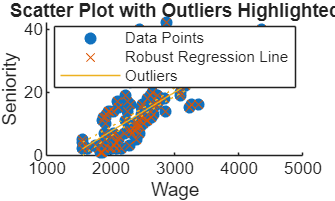

% scatter plot with outlier flagged by robust regression from table X
% Scatter plot with outlier flagged by robust regression from table X
figure;
scatter(XX.Wage, XX.Seniority, 'filled');
hold on;
mdl = fitlm(XX.Wage, XX.Seniority, 'RobustOpts', 'on');
plot(mdl);
xlabel('Seniority');
ylabel('Wage');
title('Scatter Plot with Robust Regression Line');
legend('Data Points', 'Robust Regression Line');
hold off;
% show in red point the outlier in the abover scatter plot all in one
% sacatter plot
% Add title and labels to the scatter plot
title('Scatter Plot with Outliers Highlighted');
xlabel('Wage');
ylabel('Seniority');
hold off;
% Add a legend to the scatter plot
legend('Data Points', 'Robust Regression Line', 'Outliers');
% Add a title and labels to the scatter plot
title('Scatter Plot with Outliers Highlighted');
xlabel('Wage');
ylabel('Seniority');
hold off;
% Finalize the scatter plot with outliers highlighted
hold off;

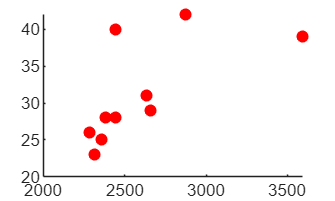


% Identify outliers based on robust regression
outliers = mdl.Residuals.Raw > 2 * mad(mdl.Residuals.Raw); % Define outliers
scatter(XX.Wage(outliers), XX.Seniority(outliers), 'r', 'filled'); % Highlight outliers in red

% using FSR function
% Identify and display the outliers in the context of the robust regression
outlierIndices = find(outliers); % Get indices of outliers
disp('Outlier Indices:');
disp(outlierIndices);

% 1. Inspect
disp(XX.Properties.VariableNames)

    {'Wage'}    {'CommutingTime'}    {'SmartWorkHours'}    {'Seniority'}



varTypes = varfun(@class, XX, 'OutputFormat', 'cell');
disp(table(XX.Properties.VariableNames(:), varTypes(:), 'VariableNames', {'Name','Class'}))

           Name             Class   
    __________________    __________

    {'Wage'          }    {'double'}
    {'CommutingTime' }    {'double'}
    {'SmartWorkHours'}    {'double'}
    {'Seniority'     }    {'double'}



Attention: there was an exact fit. Robust estimate of s^2 is <1e-7
More than half of the observations produce a linear model with a perfect fit
Number of units which entered=13
Number of units which entered=13
Number of units which entered=18
Number of units which entered=20
Number of units which entered=19
Number of units which entered=12
Number of units which entered=14


Number of units which entered=17
Number of units which entered=15
Number of units which entered=14
Number of units which entered=15
Number of units which entered=11
Number of units which entered=19
Number of units which entered=27
Number of units which entered=24
Number of units which entered=26
Number of units which entered=29
Number of units which entered=16
Number of units which entered=22

Number of units which entered=12
Number of units which entered=23
Number of units which entered=17
Number of units which entered=12
Number of units which entered=30
Number of units which entered=29
Number of units which entered=27
Number of units which entered=20
Number of units which entered=22
Number of units which entered=21
Number of units which entered=29
Number of units which entered=22

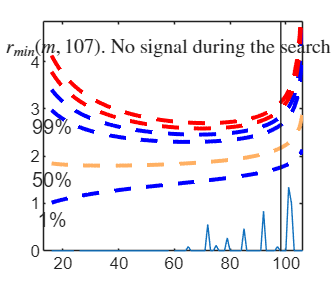

Sample seems homogeneous, no outlier has been found
Summary of the exceedances
           1          99         999        9999       99999
          89           0           0           0           0



ans =   Legend ( Units) with properties:

         String: {' Units'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.8172 0.8472 0.0789 0.0451]
          Units: 'normalized'

  Show all properties


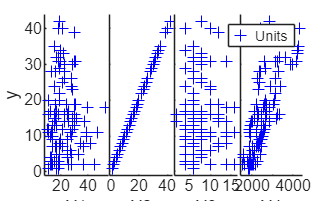


% 2. Prepare y and X (select numeric predictors)
y = XX.Seniority;                       % change "Y" to your response name
predictorNames = setdiff(XX.Properties.VariableNames, "XX");
isNum = varfun(@isnumeric, XX(:, predictorNames), 'OutputFormat', 'uniform');
numPredictors = predictorNames(isNum);
X = table2array(XX(:, numPredictors));   % numeric matrix of predictors

% If any predictor is categorical/string, convert if appropriate:
% XX.CatVar = double(categorical(XX.CatVar));

% Confirm numeric
assert(isnumeric(X) && isnumeric(y), 'y and X must be numeric.')

% 3. Call FSR (example usage)
% [y_out,X_out,n,p] = aux.chkinputR(y,X,nnargin,vvarargin) is internal;
% Typical FSR call (toolbox dependent) — adjust options as needed:
out = FSR(y, X);    % returns structure 'out' (toolbox dependent)

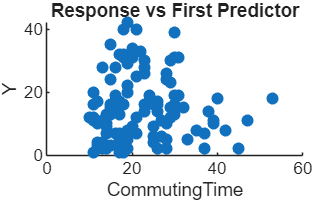


% 4. Plot: example y vs first predictor
figure
scatter(X(:,1), y, 'filled')
xlabel(numPredictors{1})
ylabel('Y')
title('Response vs First Predictor')


% Optional: if FSR returns fitted values, plot fitted vs observed
if isfield(out, 'yhat')
    figure
    plot(y, out.yhat, 'o')
    xlabel('Observed y'); ylabel('Fitted y')
    title('Observed vs Fitted')
    refline(1,0) % 45-degree reference
end
